**Transmural analysis using fabricated data**

**data_points: 5x5**

**Slices: 2**

**Read in data from slices**

warning off
clear all
close all
clc
addpath(genpath('..'));

**Test data_point**

data_point_O = data_point;

data_point_O.intensity_data = [38024 37297 35980 35775 35898 35834 36200 36092 37609 37450 37361 37287 37332 37407 37720 37901 37847 39109 39186 39195 38388 37528 37855 36427 36018 34833 34704 33482 33606 32770 32091 31760 31466 32107 31669 31114 31056 31343 29986 29408 29401 29656 29962 29919 29181 28666 28883 29010 28463 28129 27445 27332 25948 25185 25085 24155 22817 22086 21390 21039 20585 20584 20641 19816 20133 20138 19807 19908 19122 18860 18654 18923 19082 18428 18274 18369 18342 17613 17507 17849 17419 17261 17255 17019 16885 17067 17301 17591 17589 17642 17893 17757 17827 17733 18158 18325 17125 16820 16306 15463 14814 14880 14984 15282 14955 14779 14931 14831 14699 14281 13640 13553 13668 13805 13712 13580 13479 13205 13204 12925 13246 13951 14337 14104 14027 14895 15274 15680 16599 16958 16915 17234 17732 17406 17515 17992 18512 17771 17272 17168 17263 17708 18297 18332 18485 18585 19031 19819 21022 22307 22839 22997 24280 25571 26404 27083 27500 27667 28077 28996 30089 31001 32366 32535 32694 33342 33871 34601 35530 35269 34761 34109 34107 33736 34304 33860 33459 33791 34160 33823 34236 34494 34703 35417 36704 36875 37526 37256 37676 37681 38563 39850 40175 41286 42033 41263 40485 40005 39757 38449 38229 38232 37157 36351 35738 34945 34620 34210 34606 34091 33413 33248 31978 31369 30310 28976 28483 27492 26109 25272 24477 23810 23730 23983 24387 24561 24647 23776 24004 24567 24434 24799 23916 23399 23735 22857 22519 21916 21377 20904 20556 20770 20659 19910 19420 19166 18738 18339 18402 18522 18409 18443 18160 18080 17834 17953 18012 17947 17457 17443 17515 18113 18886 19152 19295 19532 18628 18054 17908 18503 18978 19124 18742 18082 17909 17912 18346 18372 19082 18720 18182 18171 17911 17907 17383 17051 16565 15824 15225 14956 14970 15228 15473 14967 15312 15890 16658 17161 17907 18794 19153 19378 19266 19280 19307 19825 20195 20270 19942 20172 19553 19020 18414 17800 17381 17656 18316 18452 18969 18846 19227 19800 20554 21561 21977 22750 22955 23270 24051 24569 24822 24957 25883 25750 25434 25720 26263 26386 26748 27871 28284 28131 28750 28978 29297 29642 30671 32948 33035 33573 32562 32178 31265 31576 32481 34625 36279 37911 38780 38535];
data_point_O = data_point_O.Normalize;
data_point_O = data_point_O.GenerateFourier(14);
data_point_O = data_point_O.GenerateTensors;
data_point_O = data_point_O.ComputeStats;

**Inspect Fits**

gamma_Ffit = evalFourier(data_point_O.an, data_point_O.bn, 1, 1:360);
gamma_FfitRad = evalFourierRad(data_point_O.an, data_point_O.bn, 1, (1:360)*pi/180);

%gamma_STFit = evalGammaST(data_point_O.D,1:360);

[theta1 theta2] = data_point_O.ComputeSymAngles;

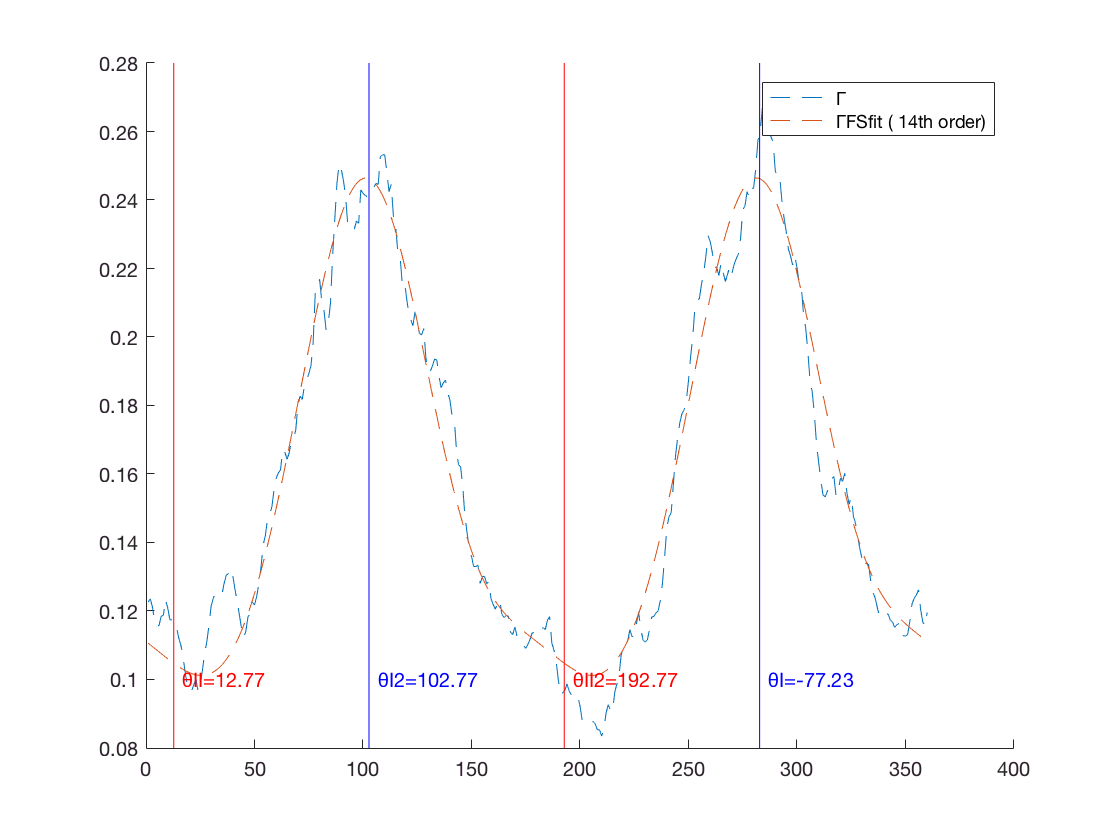

figure
hold on
plot(1:360,data_point_O.odd,'--') 
plot(1:360,gamma_FfitRad,'--') 
vline(theta1*180/pi+360,'b', sprintf('θI=%.2f',theta1*180/pi)); vline(theta1*180/pi+180,'b', sprintf('θI2=%.2f',theta1*180/pi+180)); 
vline(theta2*180/pi,'r', sprintf('θII=%.2f',theta2*180/pi)); vline(theta2*180/pi+180,'r', sprintf('θII2=%.2f',theta2*180/pi+180)); 
legend('show','Γ','ΓFSfit ( 14th order)')
hold off

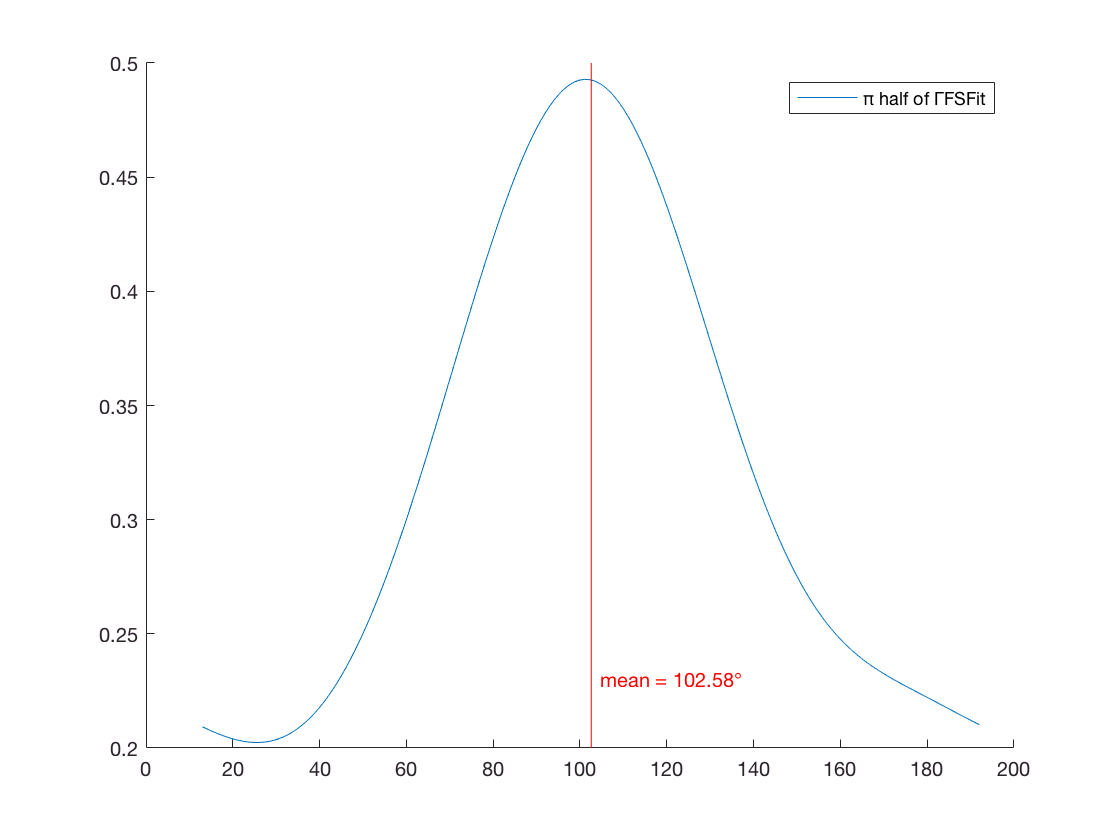

[pi_half_odf, pi_half_odf_range] = data_point_O.GetODFPiSegment();

figure
hold on
plot(pi_half_odf_range*180/pi, pi_half_odf);
legend('show','π half of ΓFSFit');
%title(sprintf('OI (perc): %.2f \n Mean (deg): %.2f \n SD (deg): %.2f', oi, mean_odf*180/pi, sd*180/pi));
vline(data_point_O.mean_odf*180/pi, 'r', sprintf('mean = %.2f°', data_point_O.mean_odf*180/pi));
hold off

**Tranformation**

Raw data is shifted according to the rotation angle.

x', y' pairs are computed from multiplication of the original position vector with the transformation matrix.

tx = 0; %% mm to the right
ty = 0;  %% mm up
theta = 45;
T = [cosd(theta) sind(theta) tx;
    -sind(theta) cosd(theta) ty; % Tranformation matrix from registration
    0 0 1];
    

tic
data_point_R = data_point_O.ApplyTransformation(T);
data_point_R = data_point_R.ComputeCoefficientsFromTensors();
data_point_R = data_point_R.ComputeStats;
toc

Elapsed time is 2.107430 seconds.


**Inspect post-rotation fits**

range = 1:360;
gamma_FfitO = evalFourier(data_point_O.an, data_point_O.bn, 1, range);

gamma_FfitR = evalFourier(data_point_R.an, data_point_R.bn, 1, range);

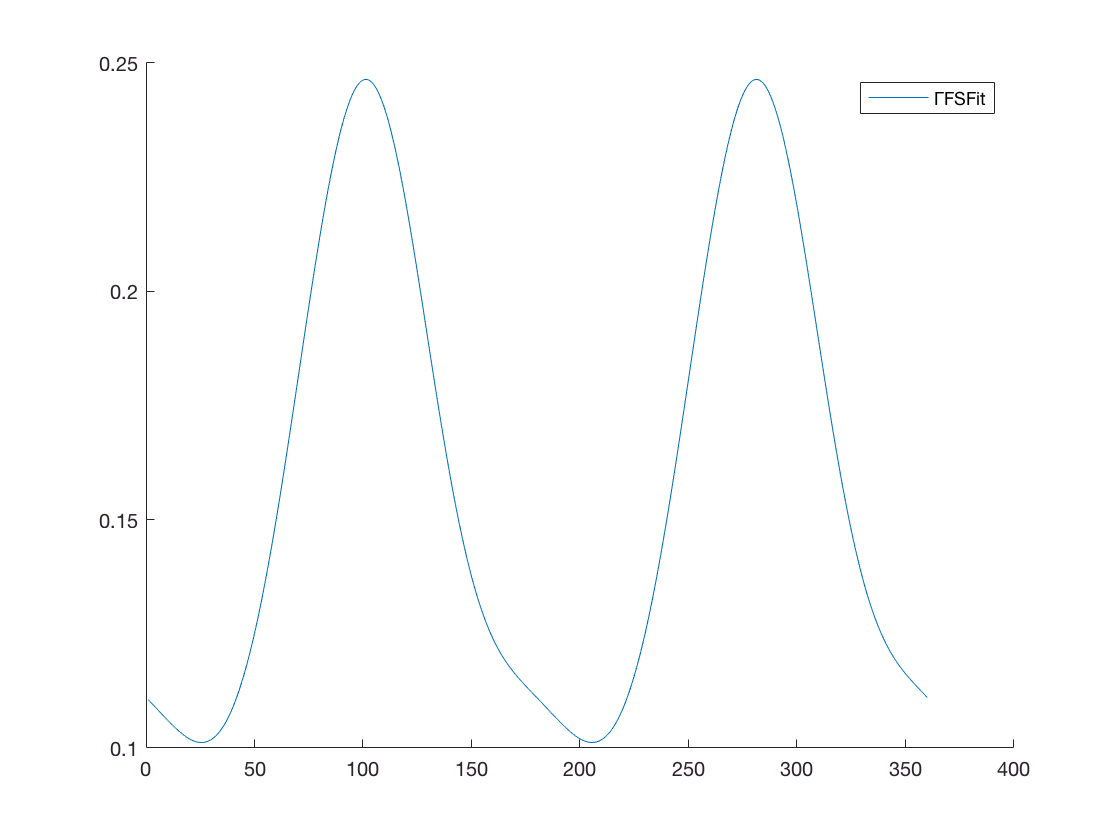

figure
hold on
plot(1:360,gamma_FfitRad)
legend('ΓFSFit');
hold off

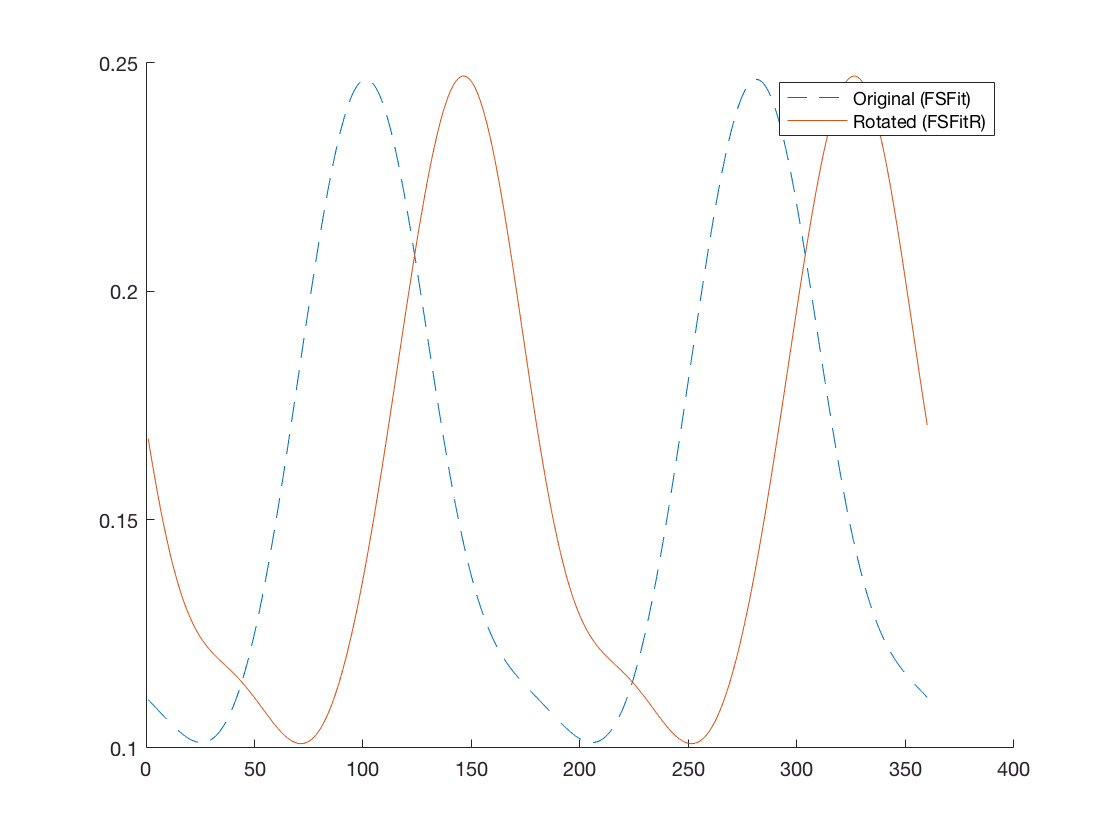


figure
hold on
plot(range, gamma_FfitO,'--') 
plot(range, gamma_FfitR)
legend('Original (FSFit)', 'Rotated (FSFitR)')%, sprintf('Rotated %.2f', theta))
hold off

**Interpolating**

An interpolation surface is created for each fourier coefficient, bit value and x,y point for a slice. 

The surface contains all triplets (x, y, value) where *value* is the fourier coefficient or bit values.

The result of the interpolation is the *value* of the surface at points x', y'

**Set up grid**

x = [data_points1(:).x];

Error: Functions cannot be indexed using {} or . indexing.


y = [data_points1(:).y];
step_size =  data_points1(2).x - data_points1(1).x;
[X1, X2] = ndgrid(0.0:step_size:x(end) , 0.0:step_size:y(end));

**New data_point Position**

x_prime = .5;
y_prime = .5;

**Interpolation step to find values for each coefficient**

an_prime = [];
for i = 1:fs_order/2 % for each coeff
   f = [];
   for j = 1:prod(size) % for each data_point
       f(j) = data_points1(j).an(i);
   end

   f_r = reshape(f, [5,5]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   an_prime(i) = F_interp(x_prime, y_prime);
end

bn_prime = [];
for i = 1:(fs_order/2) % for each coeff
   f = [];
   for j = 1:prod(size) % for each data_point
       f(j) = data_points1(j).bn(i);
   end

   f_r = reshape(f, [5,5]);
   F_interp = griddedInterpolant(X1, X2,f_r,'cubic');
   bn_prime(i) = F_interp(x_prime, y_prime);
end

d_int = data_point;
d_int.an = an_prime;
d_int.bn = bn_prime;
d_int = d_int.GenerateTensors;

figure 
C_grid = reshape(f_r, [5,5]);
surf(X1, X2, C_grid,'LineStyle', 'none', 'FaceColor', 'interp')


% Gen data from for plotting
d = evalFourier(an_prime, bn_prime, 1, 1:360);
d=d/sum(d);
figure
plot(d)
title(sprintf('Post-interpolated ODF for data_point at x=%d,y=%d', x_prime, y_prime));

figure
subplot(3,3,1); plot(1:180, data_points2(1).odf(1:180)); title(sprintf('x=%d,y=%d', data_points2(1).x, data_points2(1).y));
vline(data_points2(1).ComputeTheta1,'b', sprintf('θI=%.2f',data_points2(1).ComputeTheta1)); 

subplot(3,3,3); plot(1:180, data_points2(2).odf(1:180)); title(sprintf('x=%d,y=%d', data_points2(2).x, data_points2(2).y));
vline(data_points2(2).ComputeTheta1,'b', sprintf('θI=%.2f',data_points2(2).ComputeTheta1)); 

subplot(3,3,7); plot(1:180, data_points2(6).odf(1:180)); title(sprintf('x=%d,y=%d', data_points2(6).x, data_points2(6).y));
vline(data_points2(6).ComputeTheta1,'b', sprintf('θI=%.2f',data_points2(6).ComputeTheta1)); 

subplot(3,3,9); plot(1:180, data_points2(7).odf(1:180)); title(sprintf('x=%d,y=%d', data_points2(7).x, data_points2(7).y));
vline(data_points2(7).ComputeTheta1,'b', sprintf('θI=%.2f',data_points2(7).ComputeTheta1)); 

subplot(3,3,5); plot(1:180, d(1:180));title(sprintf('x=%.2f,y=%.2f', x_prime, y_prime));
vline(d_int.ComputeTheta1,'b', sprintf('θI=%.2f',d_int.ComputeTheta1)); 

figure
hold on;
plot(1:180, data_points2(1).odf(1:180), 'r--'); 
vline(data_points2(1).ComputeTheta1,'r--'); 
plot(1:180, data_points2(2).odf(1:180), 'r.');
vline(data_points2(2).ComputeTheta1,'r--'); 
plot(1:180, data_points2(6).odf(1:180),'g--');
vline(data_points2(6).ComputeTheta1,'g--'); 
plot(1:180, data_points2(7).odf(1:180), 'y.'); 
vline(data_points2(7).ComputeTheta1,'y--'); 
plot(1:180, d(1:180),'b');
vline(d_int.ComputeTheta1,'b'); 
legend('show','(0,0)','(1,0)','(1,0)','(1,1)', '(0.5,0.5): Interpolated')
hold off
